## Vehicular Platoons Coordination Simulator

This is the main file that one needs to execute to generate the results that we show in our paper.

clear all
close all
clc

rng(7)

Creation of the network of platoons

%% Setup
network_index = 0;                  % network Index
numOfPlatoons = 1;                  % num of platoons
numOfVehicles = [6]; %[4,5,6];            % num of vehicles in each platoon
totalNumOfVehicles = sum(numOfVehicles);

%% Initial setup
vehicleSeperationMean = 5;
vehicleSeperationVar = 2; 
platoonSeperationMean = 10;
platoonSeperationVar = 2;

%% Define the initial vehicular position/velocity/acceleration 
vehiclePosition = 0;                % Zeroth vehicle position
vehicleVelocity = 0;                % Zeroth vehicle velocity
vehicleAcceleration = 0;            % Zeroth vehicle acceleration

state_ki = [vehiclePosition; vehicleVelocity; vehicleAcceleration];
desiredSeparation_ki = 0;              % Desired separation from the leader

%% Define the initial states and desired states for all the vehicles
for k = 1:1:numOfPlatoons           % for every platoon k
    
    parameters_k = [];
    noiseMean_k = [];
    noiseStd_k = [];
    states_k =  [];                       % initial states collection
    desiredSeperation_k = [];

    for i = 1:1:numOfVehicles(k)    % for every vehicle in the k-th platoon

        % Vehicle parameters (assumed homogenuous)
        mass_ki = 1500;
        length_ki = 2.5;
        Af_ki = 2.2;
        rho_ki = 0.78;
        Cd_ki = 0.35;
        Cr_ki = 0.067;
        tau_ki = 0.25;

        % Collection of the initial/initially desired states of each vehicle
        states_k = [states_k, state_ki];
        
        % Define the vehicle position/velocity/acceleration 
        vehiclePosition = vehiclePosition - vehicleSeperationMean - vehicleSeperationVar*(rand(1)-0.5);
        vehicleVelocity = 0;
        vehicleAcceleration = 0;
        state_ki = [vehiclePosition; vehicleVelocity; vehicleAcceleration];
        

        % Desired vehicular positions 
        desiredSeperation_k = [desiredSeperation_k, desiredSeparation_ki];
        desiredSeparation_ki = desiredSeparation_ki + vehicleSeperationMean;

        % Collection of vehicle parameters
        vehicleParameters_i = [mass_ki; length_ki; Af_ki; rho_ki; Cd_ki; Cr_ki; tau_ki];
        parameters_k = [parameters_k, vehicleParameters_i];

        % Noise parameters
        noisemean_ki = rand(3,1);
        noisestd_ki = 0.1*rand(3,1);

        noiseMean_k = [noiseMean_k, noisemean_ki];
        noiseStd_k = [noiseStd_k, noisestd_ki];
            
    end
    
    vehiclePosition = states_k(1,end) - platoonSeperationMean - platoonSeperationVar*(rand(1)-0.5);
    
    state_ki = [vehiclePosition; vehicleVelocity; vehicleAcceleration];
    desiredSeparation_ki = 0;

    parameters{k} = parameters_k;
    states{k} = states_k;
    desiredSeparation{k} = desiredSeperation_k;
    noiseMean{k} = noiseMean_k;
    noiseStd{k} = noiseStd_k;
      
end

net = Network(network_index,numOfPlatoons,numOfVehicles,parameters,states,desiredSeparation,noiseMean,noiseStd);

Plotting the network of platoons

% Platoon simulation video figure setup
figure(1)
hold on 
ax1 = gca;                   % gca = get current axis handle
ax1.YAxis.Visible = 'off';   % hide out the y-axis from the plot
% axis off
% set(gcf,'Visible','off')
net.drawNetwork(1)

#### Synthesizing controllers for the platoon

**Configuration 1:** Centralized Stabilizing Control using Error Dynamics II

Note: Local passivating controller synthesis should not use a cost function in order to get a set of local controller gain coefficients that are smaller (and thus, practical).

% %%% Global controller synthesis specifications
% % Error dynamics I/II, centralized/decentralized, stabilizing/robust, and upperBound on \gamma^2
% errorDynamicsType = 2;  % Error dynamics formulation I or I
% isCentralized = 1;      % Centralized or decentralized controller synthesis
% isOnlyStabilizing = 1;  % Stabilizing controller or Disturbance robust Controller)
% gammaSqBar = 10;        % For the constraint: gamma^2 <= gammaSqBar  % Desired max noise attenuation
% 
% %%% Local passivating controller synthesis specifications 
% % LowerBound on \nu and upperBound on \rho 
% nuBar = -10;        % For the constraint: nu >= nuBar       %nuBar = -8.1
% rhoBar = 5;         % For the constraint: rho <= rhoBar     %rhoBar = 4.1

**Configuration 2:** Centralized Robust Control using Error Dynamics II

Note: In the local passivating controller synthesis, when no cost function is used, the resulting passivity indices are not amenable to global controller synthesis. 

To resolve this, we can resort to using the fundamental cost function for local passicating controller synthesis. However, this leads to: (Issue 1) larger local controller gains, and (Issue 2) global controller gains with no inter-vehicle interconnections. 

To solve the first issue, we can resort to use a cost function (in local passivating controller synthesis) of the form: 0.0000001*(- nu + rhoBar); This leads to relatively low local controller gains as well as passivity indices that are amenable to global controller synthesis. However, (Issue 2) is still a problem. 

%%% Global controller synthesis specifications
% Error dynamics I/II, centralized/decentralized, stabilizing/robust, and upperBound on \gamma^2
errorDynamicsType = 2;  % Error dynamics formulation I or I
isCentralized = 1;      % Centralized or decentralized controller synthesis
isOnlyStabilizing = 0;  % Stabilizing controller or Disturbance robust Controller)
gammaSqBar = 10;        % For the constraint: gamma^2 <= gammaSqBar % Desired max noise attenuation

%%% Local passivating controller synthesis specifications 
% LowerBound on \nu and upperBound on \rho 
nuBar = -40;       % For the constraint: nuBar <= nu       
rhoBar = 15;       % For the constraint: rhoHat <= rho <= rhoBar

%%% Parameterized approach to co-design
% Optimizing gammaSq with respect to the co-design parameters
pVals = net.optimizeCodesignParameters()

Global Synthesis Success with gammaSq=3.0366
Global Synthesis Success with gammaSq=3.0366
Global Synthesis Success with gammaSq=3.0366
Global Synthesis Success with gammaSq=3.0366
Global Synthesis Success with gammaSq=3.0366
Global Synthesis Success with gammaSq=3.0366
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    3.036554e+00    0.000e+00    1.560e-02
Global Synthesis Success with gammaSq=2.9592
Global Synthesis Success with gammaSq=2.9592
Global Synthesis Success with gammaSq=2.9592
Global Synthesis Success with gammaSq=2.9592
Global Synthesis Success with gammaSq=2.9592
Global Synthesis Success with gammaSq=2.9592
    1      12    2.959207e+00    0.000e+00    3.495e+00    1.211e-01
Global Synthesis Success with gammaSq=2.553
Global Synthesis Success with gammaSq=2.553
Global Synthesis Success with gammaSq=2.553
Global Synthesis Success with gammaSq=2.553
Global Synthesis Succ

pVals =     0.0203
    0.0203
    0.0202
    0.0202
    0.0204


fval = 2.5213

pVals =     0.0203    0.0203    0.0202    0.0202    0.0204


% Resulting optimal parameters:
% pVals = 
% Trying some fixed set of parameters.
% pVals = 0.15*ones(numOfPlatoons,max(numOfVehicles));

%%% Execution of the controller synthesis
%net.platoons(1).vehicles(2).synthesizeLocalControllers(2,nuBar,rhoBar)
net.loadPlatoonControllers(errorDynamicsType,isCentralized,isOnlyStabilizing,gammaSqBar,nuBar,rhoBar,pVals);

costFun0Val = 1.0000

costFunVal = 3.5213

PVal =     0.0192         0         0         0         0
         0    0.0192         0         0         0
         0         0    0.0191         0         0
         0         0         0    0.0191         0
         0         0         0         0    0.0193


gammaSqVal = 2.5213

K = 5×5 cell array
    {3×3 double}    {3×3 double}    {3×3 double}    {3×3 double}    {3×3 double}
    {3×3 double}    {3×3 double}    {3×3 double}    {3×3 double}    {3×3 double}
    {3×3 double}    {3×3 double}    {3×3 double}    {3×3 double}    {3×3 double}
    {3×3 double}    {3×3 double}    {3×3 double}    {3×3 double}    {3×3 double}
    {3×3 double}    {3×3 double}    {3×3 double}    {3×3 double}    {3×3 double}


Synthesis Success at Platoon 1.


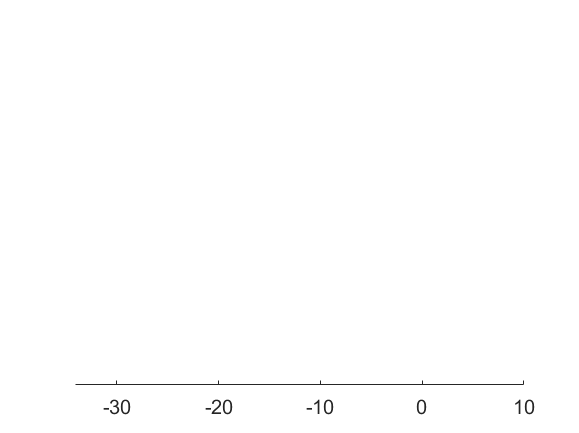

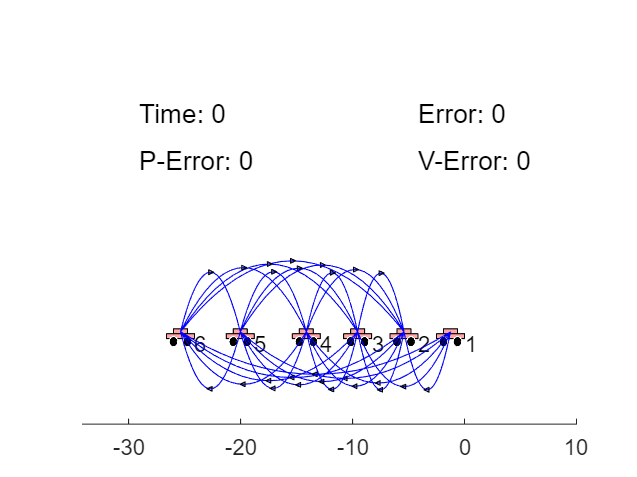


%%% Graphing the Resulting topology
figure(2)
hold on
ax1 = gca;                   % gca = get current axis handle
ax1.YAxis.Visible = 'off';   % hide out the y-axis from the plot
% axis off
% set(gcf,'Visible','off')
net.drawNetwork(2)

Running the Simulation - Updating the states

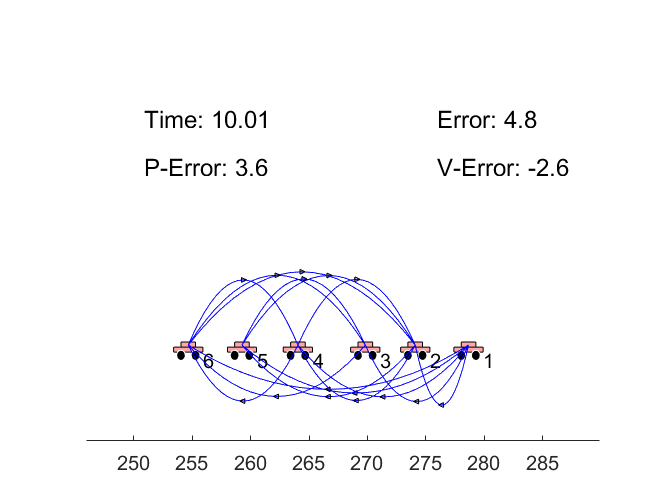

% Update the states and plot them in real time as an animation
dt = 0.01;
tMax = 10; 
tArray = 0:dt:tMax;

% Leader's trajectory specification
tVals = tMax*[0,0.2,0.4,0.6,0.8,1];     % Special time instants (inbetween which the acceleration is constant)
vVals = [0,30,40,40,20,20];  % Velocities to be achived at these time instants
net.generateLeadersControlProfiles(dt,tVals,vVals);

% Updating the platoons
for t = tArray

    % Use this update function to achieve the update of the entire program
    net.update(t,dt);
    net.redrawNetwork(2)
    pause(0.01)
    
end

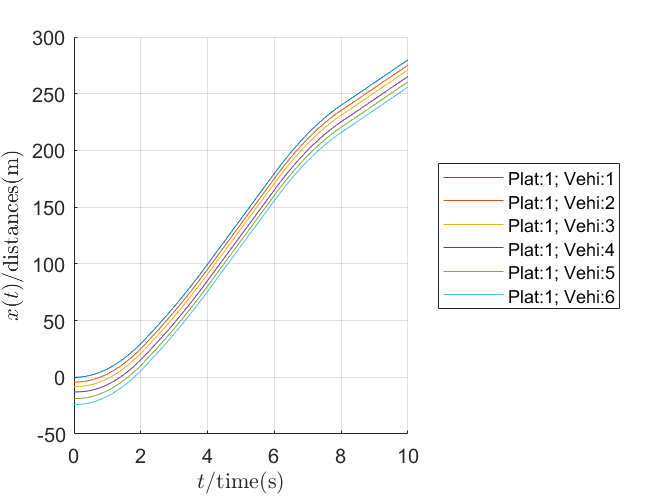

% Plot the state histories
figure
hold on
for k = 1:1:numOfPlatoons
    for i = 1:1:numOfVehicles(k)
        plot(tArray,net.platoons(k).vehicles(i).stateHistory(1,:)','-',DisplayName=['Plat:',num2str(k),'; Vehi:',num2str(i)]);
    end
end
xlabel('$t$/time(s)','Interpreter','latex')
ylabel('$x(t)$/distances(m)','Interpreter','latex')
legend(Location="eastoutside")
grid on 

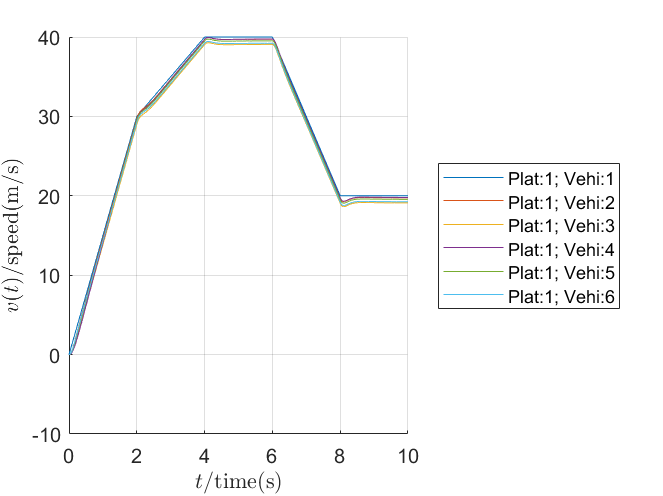


figure
hold on
for k = 1:1:numOfPlatoons
    for i = 1:1:numOfVehicles(k)
        plot(tArray,net.platoons(k).vehicles(i).stateHistory(2,:)','-',DisplayName=['Plat:',num2str(k),'; Vehi:',num2str(i)]);
    end
end
xlabel('$t$/time(s)','Interpreter','latex')
ylabel('$v(t)$/speed(m/s)','Interpreter','latex')
legend(Location="eastoutside")
grid on 

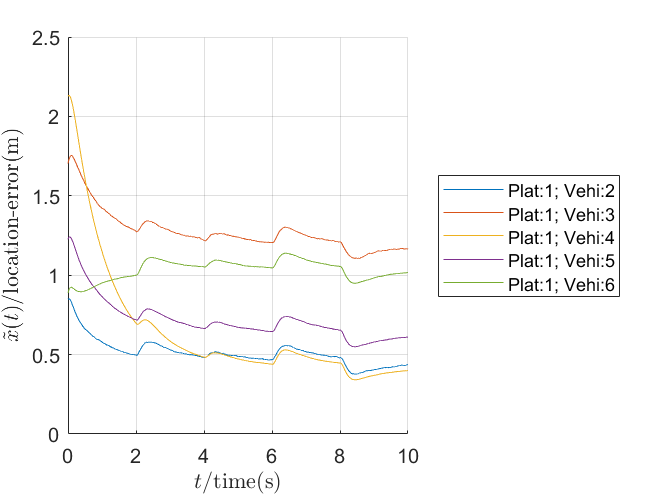


% Plot the location error histories
figure
hold on
for k = 1:1:numOfPlatoons
    for i = 2:1:numOfVehicles(k)
        plot(tArray,net.platoons(k).vehicles(i).errorHistory(1,:)','-',DisplayName=['Plat:',num2str(k),'; Vehi:',num2str(i)]);
    end
end
xlabel('$t$/time(s)','Interpreter','latex')
ylabel('$\tilde{x}(t)$/location-error(m)','Interpreter','latex')
legend(Location="eastoutside")
grid on 

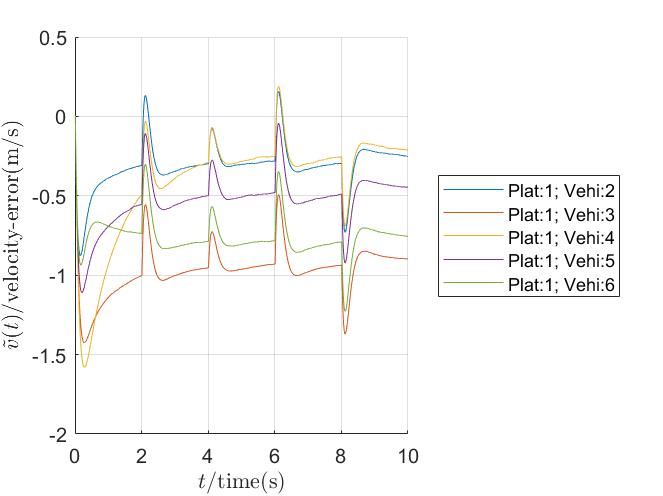


figure
hold on
for k = 1:1:numOfPlatoons
    for i = 2:1:numOfVehicles(k)
        plot(tArray,net.platoons(k).vehicles(i).errorHistory(2,:)','-',DisplayName=['Plat:',num2str(k),'; Vehi:',num2str(i)]);
    end
end
xlabel('$t$/time(s)','Interpreter','latex')
ylabel('$\tilde{v}(t)$/velocity-error(m/s)','Interpreter','latex')
legend(Location="eastoutside")
grid on 

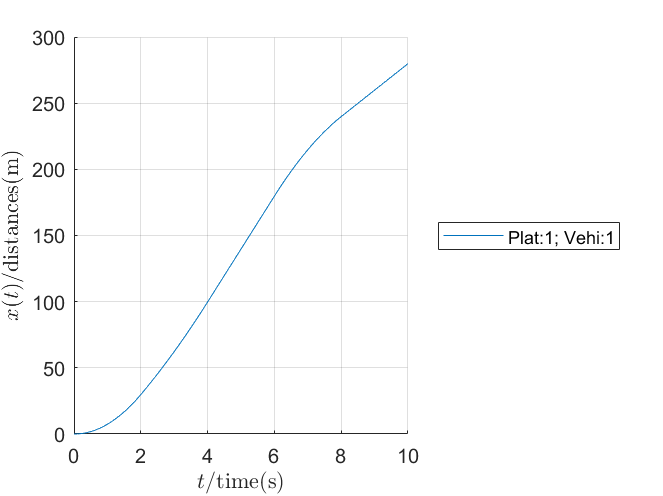



% Plot the state histories of leaders
figure
hold on
for k = 1:1:numOfPlatoons
    for i = 1
        plot(tArray,net.platoons(k).vehicles(i).stateHistory(1,:)','-',DisplayName=['Plat:',num2str(k),'; Vehi:',num2str(i)]);
    end
end
xlabel('$t$/time(s)','Interpreter','latex')
ylabel('$x(t)$/distances(m)','Interpreter','latex')
legend(Location="eastoutside")
grid on 

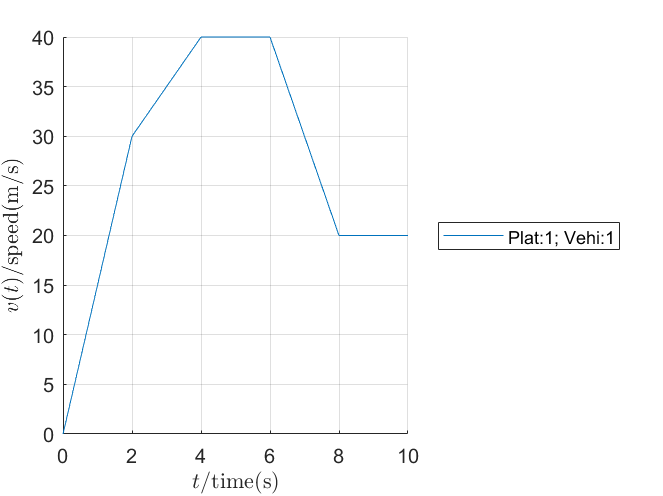



figure
hold on
for k = 1:1:numOfPlatoons
    for i = 1
        plot(tArray,net.platoons(k).vehicles(i).stateHistory(2,:)','-',DisplayName=['Plat:',num2str(k),'; Vehi:',num2str(i)]);
    end
end
xlabel('$t$/time(s)','Interpreter','latex')
ylabel('$v(t)$/speed(m/s)','Interpreter','latex')
legend(Location="eastoutside")
grid on 

Ideas to pursue next:

What is the best set of passivity information for this topology synthesis?

Leader's connection design (Centralized Setting, ED-I)

For the case with z = C e

Local controller design for passivation